clc;close all;clear all

# Création & Codage du Porteur

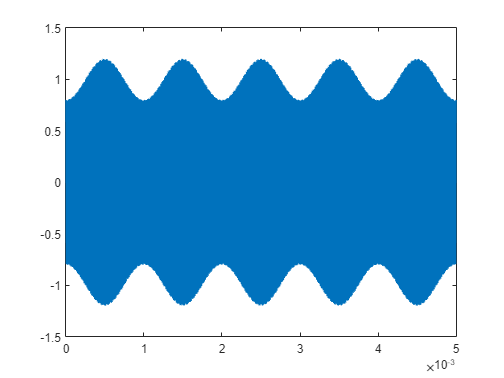

K = 1; % (randi([-10,10])/10)
a = -0.2;

f=1000 ; w=2*pi*f;
f0=83000 ; w0=2*pi*f0;

t=linspace(0,5/f,8000);

s = K*cos(w0*t).*(1+a*cos(w*t));

plot(t,s)

# Filtration par LC

ft = logspace(2,6,1000);wt = 2*pi.*ft;n=10000;
L=1e-3;C=2.7e-6;fc = 1/(2*pi*sqrt(L*C))

fc = 3.0629e+03

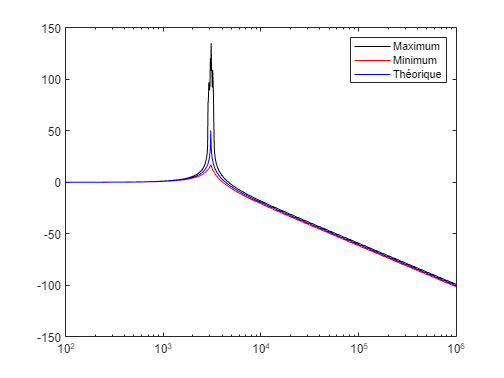

L_reel = L*(1+7/100*(2*rand(n,1)-1)); % Resistance*(1+tol_Resistance*(2*rand(n,1)-1));
C_reel = C*(1+7/100*(2*rand(n,1)-1)); % Capacité*(1+tol_Capa*(2*rand(n,1)-1));

H = (1./(C*1i.*wt))./(1i*L.*wt+1./(C*1i.*wt));

H_reel=zeros(n,length(ft));
for i=1:n
    H_reel(i,:)=(1./(C_reel(i)*1i.*wt))./(1i*L_reel(i).*wt+1./(C_reel(i)*1i.*wt));
end
H_reel_max=max(abs(H_reel)); % A tol max
H_reel_min=min(abs(H_reel)); % A tol min

semilogx(ft,20*log10(abs(H_reel_max)),'k',ft,20*log10(abs(H_reel_min)),'r',ft,20*log10(abs(H)),'b')
legend('Maximum','Minimum','Théorique')

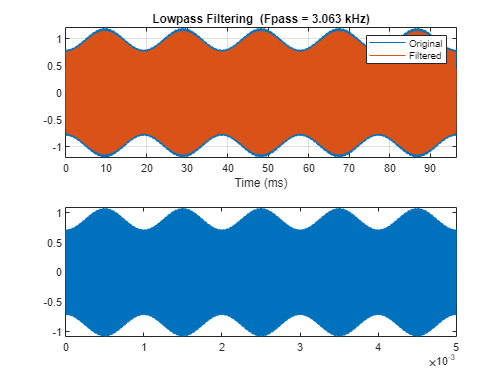

lowpass(s,fc,f0)
s1 = s*(1/(C*(2*pi*f)))/(L*(2*pi*f)+1./(C*(2*pi*f)));
plot(t,s,t,s1)